# **demo04 of writeMesh**

**Mesh with quadratic elements**

Cite as: Ma, J., & Li, Y. (2025). Im2mesh: A MATLAB/Octave package for generating finite element mesh based on 2D multi-phase image (2.1.5). Zenodo. [https://doi.org/10.5281/zenodo.14847059](https://doi.org/10.5281/zenodo.14847059)

Jiexian Ma, mjx0799@gmail.com. [Project website](https://github.com/mjx888/writeMesh).

## Initialize

clearvars

Set default image size.

x = 250; y = 250; width = 250; height = 250;
set(groot, 'DefaultFigurePosition', [x,y,width,height])
% To reset:
% set(groot, 'DefaultFigurePosition', 'factory')

## Load mesh

Let's load the mesh data from "mesh_data_4.mat"

load("mesh_data_4.mat")

We will see 2 variables. 

vert

vert =    44.5000   48.5000
   52.5000   98.5000
   76.5000  158.5000
   84.5000   96.5000
  100.5000  156.5000
  104.5000   17.5000
  104.5000   47.5000
  105.5000  205.5000
  105.5000  222.5000
  109.5000  214.5000


ele

ele =     36    17    86    97    98    99
    49    77    58   100   101   102
    77    84    88   103   104   105
    57    82    92   106   107   108
    45    71    22   109   110   111
     4    73    40   112   113   114
    87    67    66   115   116   117
    52    28    46   118   119   120
    86    35    36   121   122    99
     5    82    64   123   124   125


'ele' has 6 column so it is triangular mesh with quadratic elements.

## Plot mesh

Use function plotMeshes to plot mesh.

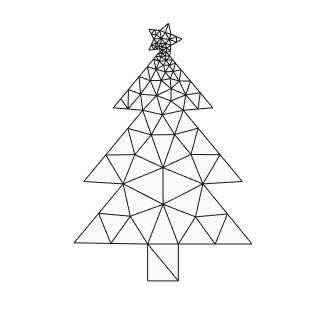

plotMeshes(vert,ele);

## Export as inp file (Abaqus)

We use function printInp2d to write 2d mesh to inp file.

The exported inp file would have a model with one part, which contains one section.

We can specify element type, precision_nodecoor and file name.

ele_type = 'CPS3';
precision_nodecoor = 8;
file_name = 'test.inp';

printInp2d( vert, ele, [], ele_type, precision_nodecoor, file_name );

printInp2d Done! Check the inp file!


## Export as bdf file (Nastran bulk data)

Function printBdf2d currently does not work for quadratic element. We will see error message.

precision_nodecoor = 8;
file_name = 'test.bdf';

printBdf2d( vert, ele, [], [], precision_nodecoor, file_name );

Error using printBdf2d (line 228)
Function printBdf2d do not support quadratic elements.

## Export as msh file (Gmsh mesh file)

Function printMsh currently does not work for quadratic element. Mesh element will be proceesed as linear elements.

precision_nodecoor = 8;
file_name = 'test.msh';

printMsh( vert, ele, [], [], precision_nodecoor, file_name );

printMsh Done! Check the msh file!


% reset image size
set(groot, 'DefaultFigurePosition', 'factory')

% end of demo